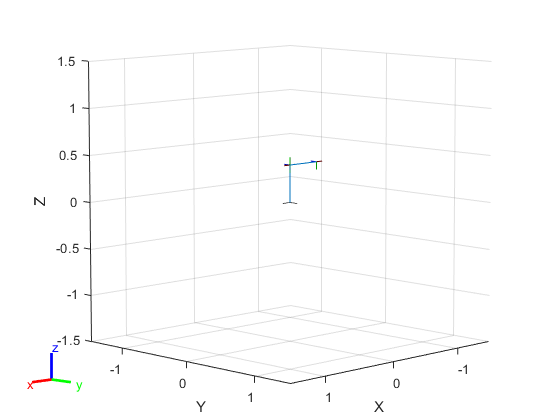

q1=sym('q1');
q2=sym('q2');
q3=sym('q3');
q4=sym('q4');

a4=sym('a4');
d1=sym('d1');

%useless unsignment
q1=pi;
q2=pi;
q3=pi;
q4=pi;

%must be small value
a4=0.4;
d1=0.4;

alpha = [pi/2, pi/2, pi/2, 0];
a=[0,0,0,a4];
d=[d1,0,q3,0];
theta=[q1,q2,pi,q4];

%Note: it has different format respect to Sveva's DHMatrix function
DHTable=[a', alpha',d',theta'];
joints = 'RRPR';
robot_model = build_robot_model(joints, DHTable);
show(robot_model); %warning! it shows the homeConfiguration in which the prismatic joints q3 is equal to zero

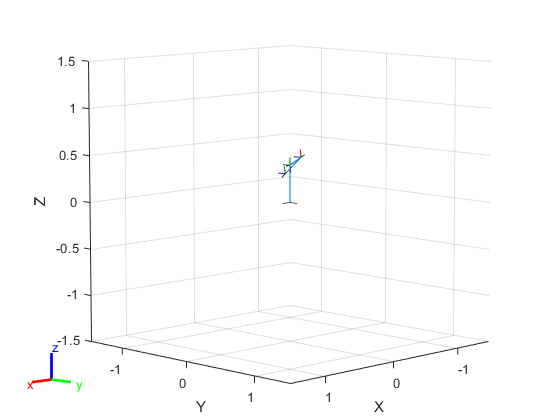

%to show a random position:
show(robot_model, randomConfiguration(robot_model));

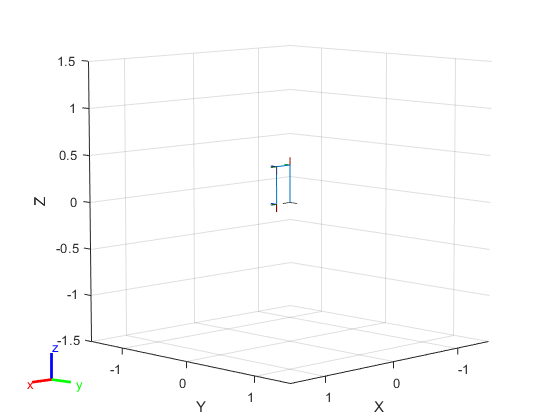

%set to position using build_configuration
q1 = 0;
q2 = pi/2;
q3 = 0.2;
q4 = 0;
array_joint_values = [q1,q2,q3,q4];
config = build_configuration(robot_model, array_joint_values);
show(robot_model, config);

function robot = build_robot_model(joints_string, DHTable)
    n_joints = length(joints_string);

    array_bodies = rigidBody.empty(n_joints,0);
    array_joints = rigidBodyJoint.empty(n_joints,0);
    
    prefix_joint_name = "joint_";
    prefix_body_name = "body_";
    
    robot = rigidBodyTree;
    
    for i = 1:n_joints
        if joints_string(i) == "R"
            joint_type = "revolute";
        elseif joints_string(i) == "P"
            joint_type = "prismatic";
        else
            joint_type = "Error";
        end
        array_bodies(i) = rigidBody(prefix_body_name+i);
        array_joints(i) = rigidBodyJoint(prefix_joint_name+i, joint_type);
        
        setFixedTransform(array_joints(i), DHTable(i,:),'dh');
        array_bodies(i).Joint = array_joints(i);
        
        if i == 1
            parent_name = 'base';
        else
            parent_name = prefix_body_name + (i-1);
        end
        addBody(robot, array_bodies(i), parent_name);
    end
end

function config = build_configuration(robot_model, array_joint_values)
    config = homeConfiguration(robot_model);
    %config = randomConfiguration(robot_model);
    if length(config) ~= length(array_joint_values)
        disp("Error! array_joints_value too small")
        return
    end
    
    for i=1:length(config)
        config(i).JointPosition = array_joint_values(i);
    end
end